% ---EXPLANATION OF PROGRAM---
% This program is meant to simulate radar recieved digital I and Q waves.
% The explanation for this can be found in Cameron Abell's capstone paper: 
% Developing Phase Processing Programs Using Simulated SFCW Radar Data.
% A doppler motion map of the data is shown as the last heatmap of the
% program, which shows the 'motion' of the simulated object, which is just
% the data created of a perfect object in scene. Since the resolution
% depends on how many points on the tilting object in frame there are,
% again, see the capstone paper, this number can be manipulated, and the
% more values, the higher the resolution, yet the slower the program will
% run. This variable is called 'point number'.

% This program was used to test this theoretically perfect data against the
% experimental data used in the actual radar signal processing. If the
% signal processing was working for theoretically perfect data, we can
% assume that the signal processing is not the problem in the radar system,
% instead it is the radar itself that is faulty.

% First clear all previous items used in before programs.

clc;
close all;
clear variables;

% THIS SECTION SETS MOST PRELIMINARY VARIABLES OF THE SYSTEM

c = physconst('lightspeed');
steps_across_bandwidth = 512;
sample_rate = 625000;
sample_time = 1 / sample_rate;
number_of_samples = 62500;
stop_time = sample_time * number_of_samples;
bw = 8*10^9;
range_res = c / (2 * bw);
unamb_range = range_res * steps_across_bandwidth;
step_size = bw / steps_across_bandwidth;
loc_freq = 500000;
flat_plate_width = 0.074948;
sphere_radius = 0.074948;
f_x = 7.1*10^10;
f_x_array = linspace(f_x,f_x + bw,steps_across_bandwidth);
t = 0:sample_time:stop_time-sample_time;
steps_across_bandwidth_index = 0:steps_across_bandwidth - 1;
index_to_bandwidth = f_x + (steps_across_bandwidth_index * step_size);
freq_after_fft = linspace(0,1,number_of_samples).* sample_rate;
amp = 1;
omega = (f_x_array .* 2 .* pi)';
index_to_distance = steps_across_bandwidth_index * range_res;
phase = 0;
az_steps = 32;
az_steps_index = 0:az_steps-1;
if rem(az_steps,2) == 1
    az_step_index_centered = linspace(-((az_steps-1)/2),((az_steps-1)/2),az_steps);
end
if rem(az_steps,2) == 0
    az_step_index_centered = linspace(-(az_steps/2),(az_steps/2)-1,az_steps);
end

point_number = 1000;
target_distance = 5.7;
target_distance_matrix = zeros(az_steps,point_number);
% target_distance_matrix(1,:) = (1:point_number)/2;
max_range = max(index_to_distance);
cross_range_res = range_res;
az_step_index_cross_range = az_steps_index .* cross_range_res;
az_step_index_centered_cross_range = az_step_index_centered .* cross_range_res;
delta = ((c/f_x) + (c/(f_x+bw)))/2; % calculate the average wavelength
total_rotation = 2*asin(delta/(4*cross_range_res)); % I set the total rotation to be calculated so
% that the resolution is square on the heat map. If you'd want a different
% total angle and don't care about the resolution being square you can make
% the next line not a comment and change as needed.
% total_rotation = 5.7; % IN DEGREES
starting_angle = -(total_rotation/2) + deg2rad(0); % Put initial starting angle in the
%deg2rad parenthases
rec_amp_array = zeros(1, az_steps) + 1; % 50.*sin(linspace(-pi,pi,az_steps));
tau = zeros(1,point_number);
rec_i = zeros(steps_across_bandwidth,point_number);
rec_q = zeros(steps_across_bandwidth,point_number);
iqar = zeros(steps_across_bandwidth,point_number);

% DEFINE SHAPE OF THE THING IN THE SCENE
shape = "flat plate";

% FOR FLAT PLATE, DEFINE TARGET DISTANCE FOR EACH AZIMUTH STEP AND ROTATION
if shape == "flat plate"
    mirror_res = flat_plate_width/(point_number-1);
    angle_array = linspace(starting_angle,starting_angle + total_rotation, az_steps)';
    x = 0:1:point_number - 1; % x is a variable used in the calculation of the
    %flat plate ranges. Essentially it is the distance from the center of the
    %flat plate to the point in the flat plate where the distance is being
    %measured. I calculate this first, because it makes the trig easier later.
    if rem(point_number,2) == 0
        x = (mirror_res.*(((point_number - 2)/2)-x))+(mirror_res/2);
    end
    if rem(point_number,2) == 1
        x = mirror_res.*(((point_number - 1)/2)-x);
    end
    x_axis_array = target_distance + (x .* asin(angle_array));
    y_axis_array = abs(x .* acos(angle_array));
    target_distance_matrix = sqrt((x_axis_array.^2)+(y_axis_array.^2));
end

% FOR SPHERE, DEFINE TARGET DISTANCE FOR EACH AZIMUTH STEP AND ROTATION

% NOTE!!!!! THE RANGE FOR THE SPHERE IS TO THE DIRECT CENTER OF THE SPHERE,
% WHERE THE SPHERE ROTATES AROUND. IT IS NOT TO THE NEAREST POINT ON THE SPHERE
if shape == "sphere"
    max_angle_seen = acos(sphere_radius/target_distance);
    x = 0:1:point_number - 1;
    x = ((point_number -1)/2) - x;
    angle_between_points = max_angle_seen / ((point_number -1)/2);
    x = angle_between_points .* x;
    x_axis_array = target_distance - (sphere_radius .* cos(x));
    y_axis_array = sphere_radius .* sin(x);
    target_distance_matrix = ones(az_steps,1) .* sqrt((x_axis_array.^2)+(y_axis_array.^2));

end

% THIS SECTION CREATES THE TRANSMITTED WAVE

transmit_wave = amp .* cos((omega .* t) + phase);

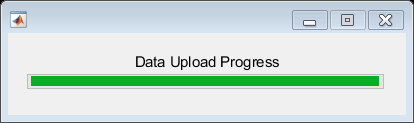

% LOOP - DE - LOOP

iqaraaz = zeros(steps_across_bandwidth,az_steps);

bigloop_index = 1;
data_prog = waitbar(bigloop_index/az_steps,'Data Upload Progress');

while az_steps >= bigloop_index

    % THIS IS WHERE THE RECIEVED WAVE IS CALCULATED
    
    % THE ONLY VARIABLES THAT I REALLY WANT TO PUT IN IS DISTANCE TO TARGET AND
    % FROM THIS TO SEE THE RECIECED WAVE. BECAUSE OF THIS I WILL, FROM THE
    % TARGET DISTANCE, CALCULATE TAU, WHICH IS THE TWO WAY TRAVEL TIME OF THE
    % RADAR WAVE TO AND FROM THE TARGET. THIS WILL THEN BE USED TO CALCULATE
    % THE RECIEVED WAVE
    
    rec_amp = 1;% rec_amp_array(bigloop_index); % IMPORTANT NOTE!!!!!!! Recieved amplitude is not always consistent with transmitted
    % amplitude so I am just setting a variable for it here. If I at some time
    % find a correlation between recieved and transmitted amplitude I will put
    % the equation to find it here.
    loop_index = 1;

    tau(1,:) = (2 .* target_distance_matrix(bigloop_index,:)) ./ c;
    rec_i = rec_amp .* cos(-omega .* tau);
    rec_q = rec_amp .* sin(-omega .* tau);

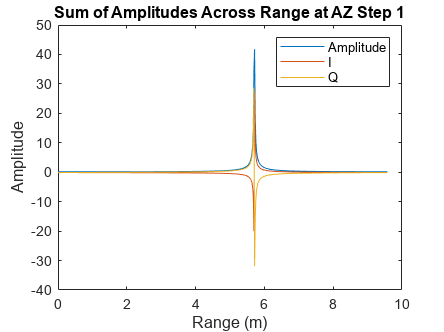

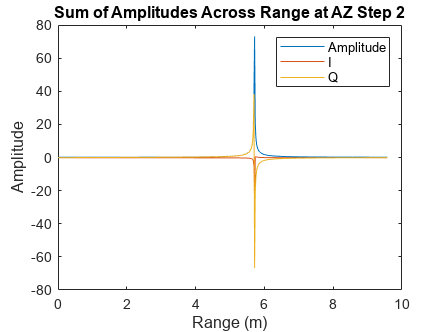

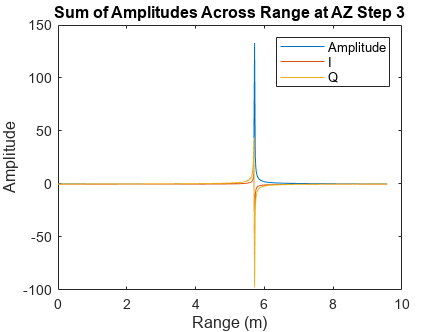

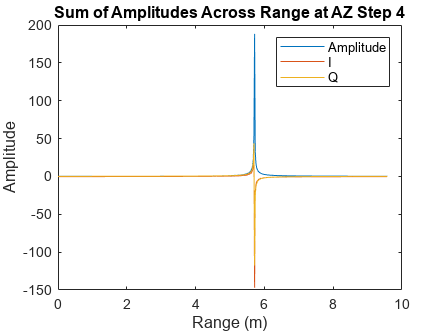

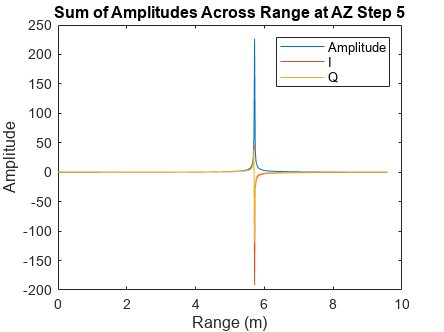

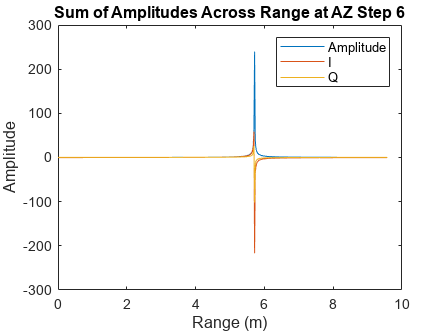

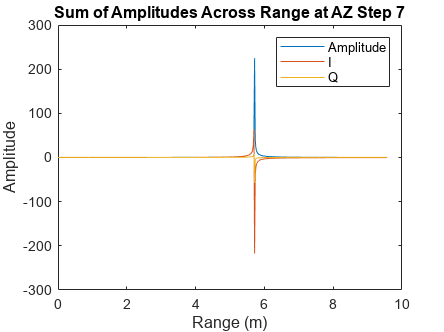

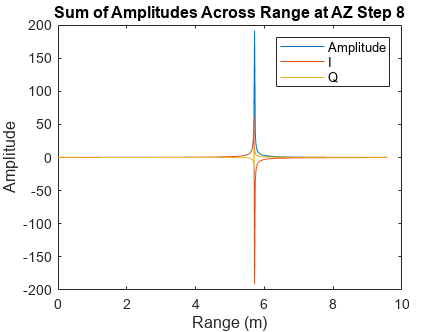

%         % THIS IS THE SECTION WHERE I DO AN IFFT ON THE I AND Q ACROSS THE
%         % BANDWIDTH OF THE RECIEVED WAVE TO GET THE DISTANCE OF THE OBJECT IN SCENE

    rec_fft = ifft(complex(rec_i,rec_q),[],2);
    rec_fft_sum = sum(rec_fft,2);


    rec_i_sum = sum(rec_i,2);
    rec_q_sum = sum(rec_q,2);
    iqar_sum = ifft(complex(rec_i_sum,rec_q_sum));

    figure
    plot(index_to_distance,abs(iqar_sum));

    hold on
    plot(index_to_distance,real(iqar_sum));
    plot(index_to_distance,imag(iqar_sum));
    title('Sum of Amplitudes Across Range at AZ Step ' + string(bigloop_index));
    xlabel('Range (m)');
    ylabel('Amplitude');
    legend('Amplitude','I','Q');
    hold off


% RETURN OF LOOP - DE - LOOP
    iqaraaz(1:steps_across_bandwidth,bigloop_index) = iqar_sum;

    bigloop_index = bigloop_index + 1;
    waitbar((bigloop_index)/az_steps);
end

newwav3 = fftshift(ifft(iqaraaz,[],2),2);

delete(data_prog); %Delete the waitbar

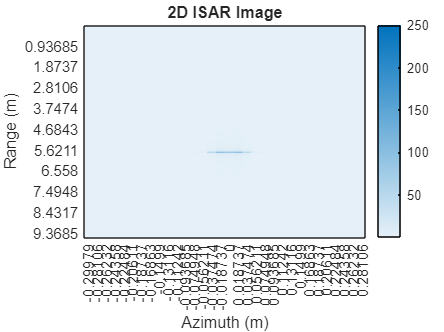

figure

h=heatmap(abs(newwav3),'CellLabelColor','auto');
h.GridVisible='off';
h.YLabel='Range (m)';
h.XLabel='Azimuth (m)'; 
h.Title='2D ISAR Image';

YLabels = 1:steps_across_bandwidth;

% Convert each number in the array into a string
CustomYLabels = string(YLabels);
CustomXLabels = az_step_index_centered_cross_range;
% Replace all but the fifth elements by spaces
CustomYLabels(mod(YLabels,50) ~= 0) = " ";
CustomYLabels = str2double(CustomYLabels);
CustomYLabels = CustomYLabels * range_res;
CustomYLabels = string(CustomYLabels);
 
% Set the 'XDisplayLabels' property of the heatmap 
% object 'h' to the custom x-axis tick labels
h.YDisplayLabels = CustomYLabels;
h.XDisplayLabels = CustomXLabels;